clc; clear; close all;


## Identifikace

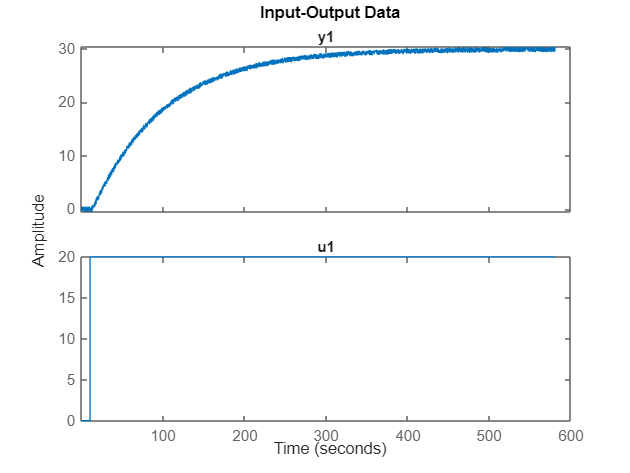


d  = readmatrix('sys_data.csv', 'Delimiter', ',');
u  = d(:,2);            % výkon ohřevu [%]
y  = d(:,4);            % teplota vody [°C]
Ts = 0.1;               % vzorkovací perioda [s]

% oříznout na okolí skoku (10 s před skokem)
k0 = find(u > u(1) + 1, 1);
u  = u(k0-100:end);   
y = y(k0-100:end);

% nulové počáteční podmínky -> odečíst ustálený začátek
du = u - u(1);
dy = y - mean(y(1:100));

data = iddata(dy, du, Ts);
plot(data)                              % kontrola: statická soustava, žádný překmit?

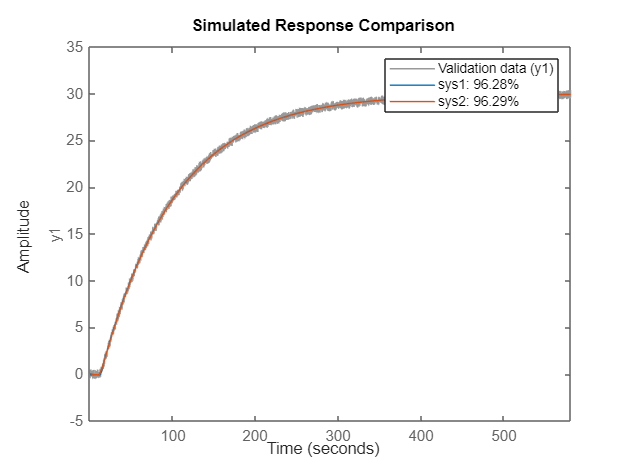


sys1 = tfest(data, 1, 0, NaN);          % 1. řád + dopravní zpoždění
sys2 = tfest(data, 2, 0);               % 2. řád
compare(data, sys1, sys2)               % vyber model s lepším "fit" (ideálně > 95 %)

## Regulátor

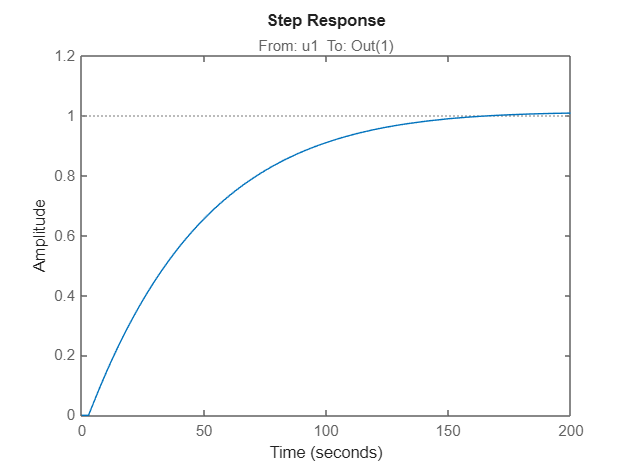


% C  = pidtune(sys1, 'PI');
% Cs = pidstd(C)                          % Kp, Ti ve tvaru Kp*(1 + 1/(Ti*s))
% C  = pidTuner(sys1, 'PI')               % Ladění Regulátoru
C = load("regulator.mat").C;
step(feedback(C*sys1, 1))              % odezva uzavřené smyčky

## Simulace

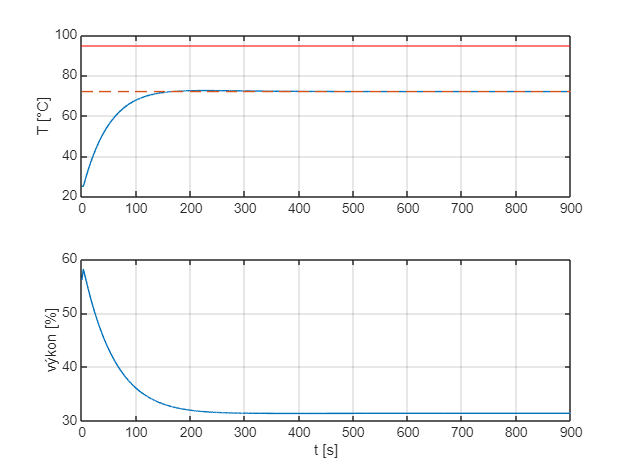

Kp = C.Kp;  Ti = C.Ti;           % z PID Tuneru (Form: Standard)
Ts = 0.1;                         % stejně jako PLC
T0 = 25;  Tset = 72;              % počáteční a žádaná teplota [°C]

sysd = absorbDelay(c2d(ss(sys1), Ts));   % model -> diskrétní (vč. zpoždění)
N = round(900/Ts);                        % simulace 900 s
x = zeros(size(sysd.A,1),1);  I = 0;
y = zeros(N,1);  u = zeros(N,1);

for k = 1:N
    yk = sysd.C*x;                    % odchylka teploty od 25 °C
    e  = (Tset - T0) - yk;
    v  = Kp*e + I;                    % PI
    uk = min(max(v, 0), 100);         % saturace výkonu 0–100 %
    if v == uk                        % anti-windup (clamping): integruj jen mimo saturaci
        I = I + Kp*Ts/Ti*e;
    end
    x = sysd.A*x + sysd.B*uk;
    y(k) = yk + T0;  u(k) = uk;
end

t = (0:N-1)*Ts;
subplot(2,1,1); plot(t, y, t, Tset*ones(size(t)), '--'); yline(95,'r'); ylabel('T [°C]'); grid on
subplot(2,1,2); plot(t, u); ylabel('výkon [%]'); xlabel('t [s]'); grid on

fprintf('max. teplota: %.1f °C, překmit: %.1f °C\n', max(y), max(y) - Tset);

max. teplota: 72.5 °C, překmit: 0.5 °C
